# Séance 1 : 

## 1. Calcul de l'expression récurrente d'un premier ordre par les 4 méthodes de discrétisation

Le système que nous allons analyser à la fonction de transfert suivante:


$$H(s) = \frac{1}{s+1}$$


**a) Euler à gauche (forward)**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode d'Euler à gauche, on doit remplacer les *s* par 


$$s \to \frac{z-1}{h}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Euler1}(z) = \frac{1}{\frac{z-1}{h} + 1} = \frac{h}{z-1+h}$$


**b) Euler à droite (backward)**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode d'Euler à droite, on doit remplacer les *s* par 


$$s \to \frac{z-1}{hz}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Euler2}(z) = \frac{1}{\frac{z-1}{hz} + 1} = \frac{hz}{z-1+hz} = \frac{hz}{z(h+1)-1}$$


**c) Bilinéaire**

Pour obtenir l'équation du système discrétisé à l'aide de la méthode bilinéaire (Tustin), on doit remplacer les *s* par 


$$s \to \frac{2(z-1)}{h(z+1)}$$


Si on fait ça, on obtient le système discrétisé suivant:


$$H_{d,Bilinéaire}(z) = \frac{1}{\frac{2(z-1)}{h(z+1)} + 1} = \frac{h(z+1)}{2(z-1) + h(z+1)}$$


**d) Equivalent échantilloné bloqué**

Pour obtenir l'équation du système discrétisé à l'aide de la zoH (Zero-Order Holder), on utilise la relation suivante :


$$\left(1-z^{-1} \right)∗Z\left(\frac{H\left(s\right)}{s}\right)$$


en remplaçant par la fonction de transfert H(s) on obtient :


$$\left(\frac{z-1}{z}\right)∗Z\left(\frac{\frac{1}{s+1}}{s}\right)=\left(\frac{z-1}{z}\right)∗Z\left(\frac{1}{s\left(s+1\right)}\right)=\left(\frac{z-1}{z}\right)∗Z\left(\frac{1}{s}-\frac{1}{s+1}\right)$$


après résolution de la transformée en Z on obtient :


$$\left(\frac{z-1}{z}\right)\left(\frac{z}{z-1}-\frac{z}{z-e^{-T} }\right)$$


Après simplification on obtient le système discrétisé suivant  :


$$\frac{1-e^{-T} }{z-e^{-T} }$$


où T est la période d'échantillonnage. 

## 2. Créer un script Matlab qui montre:

**a) Les réponses temporelles des quatre expressions trouvées comparées avec la réponse exacte du système continu. ** 

h = 0.1;
s = tf('s');
z = tf('z', h);

Hc = 1 / (s + 1)


Hc =
 
    1
  -----
  s + 1
 
Continuous-time transfer function.




% Euler à gauche
sg = (z - 1)/h;
Hg = 1 / (sg + 1)


Hg =
 
    0.1
  -------
  z - 0.9
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% Euler à droite
sd = (z-1)/(h*z);
Hd = 1 / (sd + 1)


Hd =
 
    0.1 z
  ---------
  1.1 z - 1
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% Bilinéaire
Hb = c2d(Hc, h, 'tustin')


Hb =
 
  0.04762 z + 0.04762
  -------------------
      z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.




% ZOH
Hzoh = c2d(Hc, h)


Hzoh =
 
   0.09516
  ----------
  z - 0.9048
 
Sample time: 0.1 seconds
Discrete-time transfer function.



Maintenant que nous avons nos fonctions de transferts discrétisés par les 4 méthodes dans Matlab, nous pouvons les analyser. Nous allons commencer par faire un plot de leurs réponse indicielle par rapport a celle du système continu.

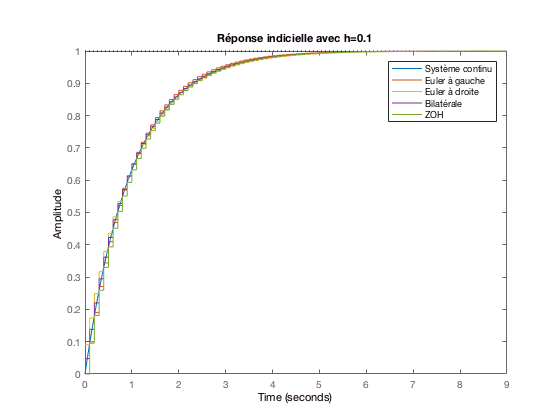

hold on;
step(Hc);
step(Hg);
step(Hd);
step(Hb);
step(Hzoh);
legend('Système continu', 'Euler à gauche', 'Euler à droite', 'Bilatérale', 'ZOH');
title("Réponse indicielle avec h=0.1");
hold off;

**b) L'influence de la période d'échantillonage h** 

On peut répéter les étapes ci-dessus pour des valeurs de *h* différentes. Prenons par exemple *h = 0.01*, *h = 0.5* et *h = 1.0*.

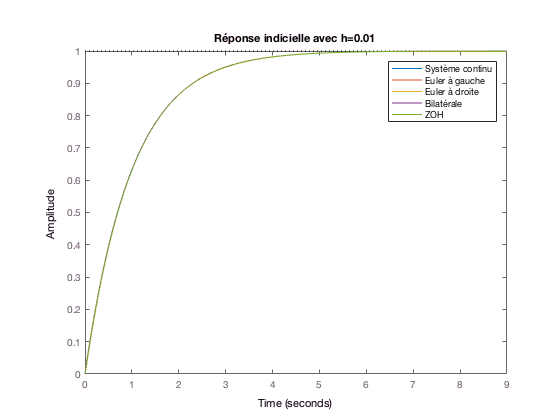

openfig('comp_h_0_01.fig');

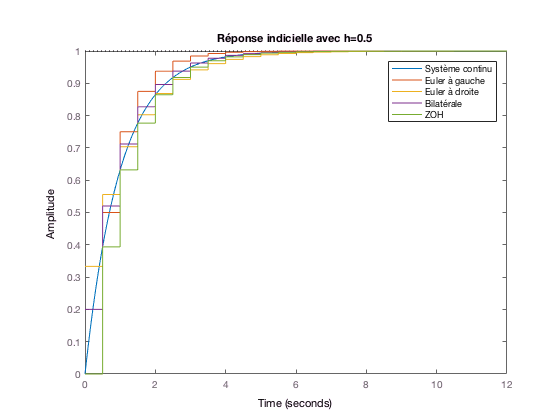

openfig('comp_h_0_5.fig');

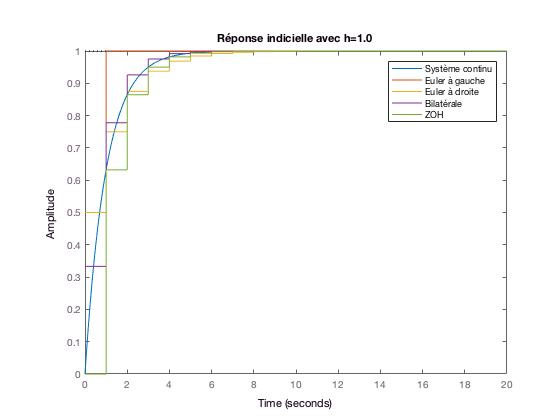

openfig('comp_h_1_0.fig');

On peut voir que pour une petite période d'échantillonage, la discrétisation colle très bien au système réel. Mais quand la période d'échantillonage augmente, les sytèmes discrétisés sont de plus en plus grossiers. 

La période d'échantillonage a également un effet sur les pôles.

h1 = 0.1;
h2 = 0.5;
h3 = 1.0;
h4 = 2.0;
h5 = 4.0;
z1 = tf('z', h1);
z2 = tf('z', h2);
z3 = tf('z', h3);
z4 = tf('z', h4);
z5 = tf('z', h5);

Pour la discrétisation avec Euler à gauche, nous pouvons voir sur la figure ci-dessous que les pôles se déplacent vers la gauche quand la période d'échantillonage augmente. Nous pouvons également tirer cette conclusion par l'équation trouvée plus haut. Le pôle est donné par:


$$p = 1-h$$


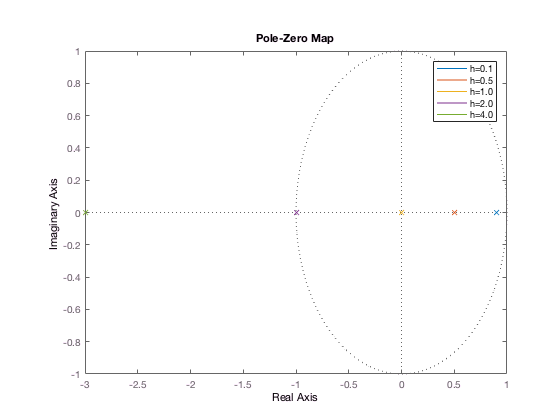

% Euler à gauche
sg1 = (z1 - 1)/h1;
sg2 = (z2 - 1)/h2;
sg3 = (z3 - 1)/h3;
sg4 = (z4 - 1)/h4;
sg5 = (z5 - 1)/h5;
Hg1 = 1 / (sg1 + 1);
Hg2 = 1 / (sg2 + 1);
Hg3 = 1 / (sg3 + 1);
Hg4 = 1 / (sg4 + 1);
Hg5 = 1 / (sg5 + 1);

figure;
pzmap(Hg1, Hg2, Hg3, Hg4, Hg5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la discrétisation avec Euler à droite, nous pouvons voir que les pôles se déplacent également vers la gauche, mais pas de façon linéaire. Par l'équation, on obtient que le pôle est donné par:


$$p = \frac{1}{h+1}$$


Le pôle va donc tendre vers zéro et non plus vers l'infini négatif.

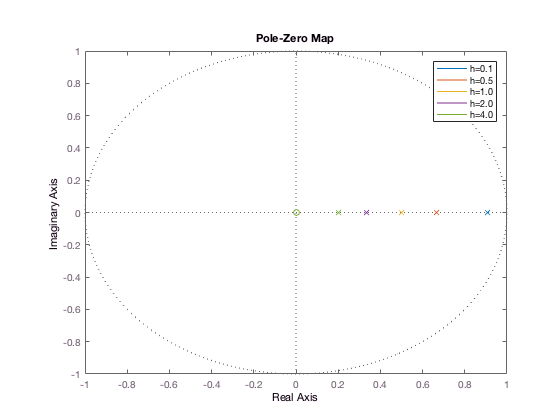

% Euler à droite
sd1 = (z1 - 1)/(h1*z1);
sd2 = (z2 - 1)/(h2*z2);
sd3 = (z3 - 1)/(h3*z3);
sd4 = (z4 - 1)/(h4*z4);
sd5 = (z5 - 1)/(h5*z5);
Hd1 = 1 / (sd1 + 1);
Hd2 = 1 / (sd2 + 1);
Hd3 = 1 / (sd3 + 1);
Hd4 = 1 / (sd4 + 1);
Hd5 = 1 / (sd5 + 1);

figure;
pzmap(Hd1, Hd2, Hd3, Hd4, Hd5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la méthode bilinéaire, le pôle est donné par l'équation:


$$p = \frac{2-h}{2+h}$$


On peut donc voir que pour la valeur de *h = 2*, le pôle se retrouve à 0 et si h augmente encore le pôle va tendre vers -1.

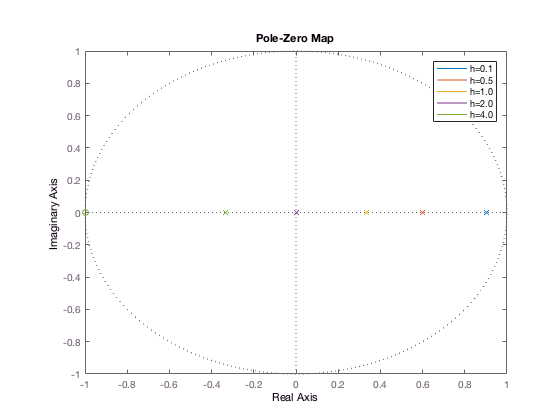

% Bilinéaire
Hb1 = c2d(Hc, h1, 'tustin');
Hb2 = c2d(Hc, h2, 'tustin');
Hb3 = c2d(Hc, h3, 'tustin');
Hb4 = c2d(Hc, h4, 'tustin');
Hb5 = c2d(Hc, h5, 'tustin');

figure;
pzmap(Hb1, Hb2, Hb3, Hb4, Hb5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

Pour la méthode de discrétisation 'Sample and Hold', les pôles ***???***

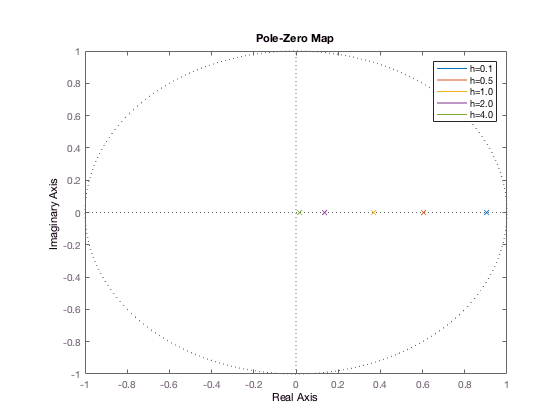


% ZOH
Hzoh1 = c2d(Hc, h1);
Hzoh2 = c2d(Hc, h2);
Hzoh3 = c2d(Hc, h3);
Hzoh4 = c2d(Hc, h4);
Hzoh5 = c2d(Hc, h5);

figure;
pzmap(Hzoh1, Hzoh2, Hzoh3, Hzoh4, Hzoh5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

**c) Quelle(s) méthode(s) de discrétisation rend(ent) le système discrétisé instable **

Par les résultats obtenus précédamment, nous pouvons tirer les conclusions suivants:

La méthode de Euler par la gauche peut rendre le système instable en le discrétisant pour des valeurs de *h* qui sont grandes. Mais nous pouvons dire que si le système discret est stable, alors le système continu l'est obligatoirement aussi.

La méthode de Euler par la droite ne rendra jamais un système instable en le discrétisant. Donc si le système continu est stable, le système discrétisé le sera également, indépendamment de la période d'échantillonage choisit.

La méthode bilinéaire ne rendra également jamais un système instable en le discrétisant. Si le système continu est stable, le système discrétisé le sera aussi, indépendamment de la période d'échantillonage choisit. De plus, si le système discrétisé est stable nous pouvons également dire que le système continu l'est nécessairement aussi.

**d)** **Une comparaison des réponses fréquentielles**

Operation terminated by user during ltipack.zpkdata/fresp (line 24)


In ltipack.ltidata/allmargin (line 88)
         ph = angle(fresp(Dzpk,wc0));

In 

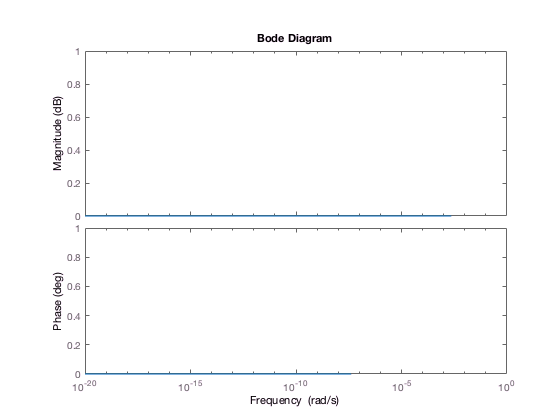

margin(Hc);

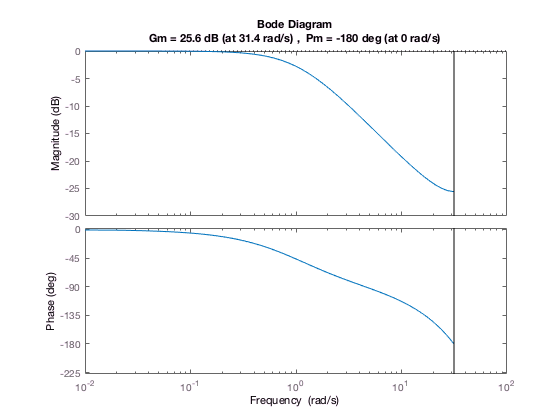

margin(Hg);

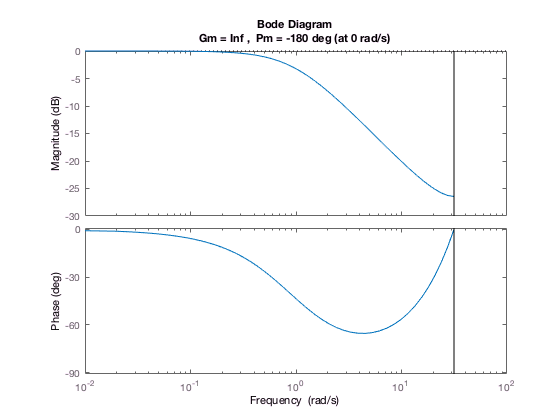

margin(Hd);

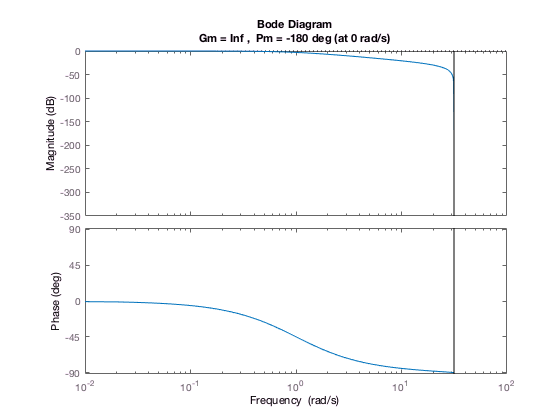

margin(Hb);

margin(Hzoh);

## 3. Calcul du gain critique d'un système du premier ordre bouclé avec un régulateur P

Un système de premier ordre à une fonction de transfert de la forme:


$$G_o(s) = \frac{K_o}{1+sT}$$


Si on veut implémenter un système de premier ordre bouclé avec un régulateur P, on obtient quelque chose comme dans le diagramme suivant.

La transmittance en boulce ouverte vaut alors:


$$G_{oc} = G_c \cdot G_o = K_p \cdot \frac{K}{1+sT}$$


Et on sait alors que la transmittance en boucle fermée vaut:


$$G_f = \frac{G_{oc}}{1 + G_{oc}} = \frac{\frac{K_p K_o}{1 + sT}}{1 + \frac{K_pK_o}{1 + sT}} = \frac{K_p K_o}{sT + 1 + K_pK_o} $$


Pour un système de premier ordre, la phase ne coupera jamais -180° et le système n'est donc jamais instable. On peut vérifier ça à l'aide de Matlab

Ko = 1;
Kp = 1;
T = 3;
Go = Ko / (1+s*T);
R = Kp;
Goc = R * Go;
Gf = Goc / (1 + Goc);
margin(Gf);

Par contre, en discret, la fréquence d'échantillonage à un effet sur la stabilité du système.


$$G_o(z) = \frac{K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right) }{z - e^{ \frac{ -T_s}{T}}}$$



$$G_f(z) = \frac{K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right) }{z - e^{ \frac{ -T_s}{T}} + K_pK_o \left( 1 - e^{ \frac{ -T_s}{T}} \right)}$$


On peut voir que le pôle est donné par l'équation


$$z = K_pK_o \left( e^{ \frac{ -T_s}{T}} - 1 \right) + e^{ \frac{ -T_s}{T}} $$


Le système est stable si le module du pôle est < 1.

$|z| = 1 \Rightarrow K_pK_o < \frac{1 + e^{\frac{-T_s}{T}}}{1 - e^{\frac{-T_s}{T}}}$           ou           $T_s < T \ln \frac{1 - K_pK_o}{1 + K_pK_o}$

On peut voir que le temps d'échantillonage à une influence sur la stabilité du système. Et on peut vérifier ça à l'aide de Matlab

K = Kp * Ko;
T = 3;
Goz1 = (K * (1 - exp(-h1/T)))/(z1-exp(-h1/T) + K * (1 - exp(-h1/T)));
Goz2 = (K * (1 - exp(-h2/T)))/(z2-exp(-h2/T) + K * (1 - exp(-h2/T)));
Goz3 = (K * (1 - exp(-h3/T)))/(z3-exp(-h3/T) + K * (1 - exp(-h3/T)));
figure;
hold on;
margin(Goz1);
margin(Goz2);
margin(Goz3);
legend("h=0.1", "h=0.5", "h=1.0");
hold off;

On peut voir que le système devient de plus en plus instable, les marges de stabilités diminuent, quand la période d'échantilonnage augmente.

## 4. Déplacement des zéros du système échantillonné avec la période d'échantillonnage  

On utilise le système suivant pour analyser le déplacement des zéros en fonction de la période d'échantillonage:


$$H(s) = \frac{1}{(s+1)^3}$$


Hq4 = 1 / (s + 1)^3;
Hq4d1 = c2d(Hq4, h1);
Hq4d2 = c2d(Hq4, h2);
Hq4d3 = c2d(Hq4, h3);
Hq4d4 = c2d(Hq4, h4);
Hq4d5 = c2d(Hq4, h5);
figure;
hold on;
pzmap(Hq4d1);
pzmap(Hq4d2);
pzmap(Hq4d3);
pzmap(Hq4d4);
pzmap(Hq4d5);
legend("h=0.1", "h=0.5", "h=1.0", "h=2.0", "h=4.0");

On peut voir que les zéros se déplacent vers le centre quand on augmente la période d'échantillonage.

# Séance 2 : Comparaison de régulateur continu et discret 

Cette séance à pour but de comparer deux types de synthèse de régulateur discret. La première méthode étudiée consiste à synthétiser un régulateur continu pour ensuite le discrètiser et la seconde méthode consiste à discrètiser le système à réguler dans un premier temps pour ensuite synthétiser un régulateur sur base de ce système discret

Soit le système H(s)


$$\frac{7\text{ }\left(s+1\right)}{s\left(3s+1\right)}$$


H = tf([7 7],[3 1 0]);

## Synthèse d'un régulateur continu avant discrètisation

Dans cette section, c'est la première méthode qui est suivie. 

L'objectif est de créer un régulateur continu pour qu'en boucle fermée ce dernier respecte les conditions suivantes :

- pas de dépassement 

- un temps de réponse de 5 à 95% (3T)

Nous avons alors conçu un régulateur de compensation en simplifiant pôle et zéros tout en conservant l'intégrateur 

pzmap(H)
grid

Le régulateur va simplifier le **pôle en 0.33 **ainsi que le zéro en -1. Le gain d'**Evans (kc) **sera alors de 2.33 avant correction

[Zc, Pc, kc] = zpkdata(H, 'v');
R = zpk(Pc(2), Zc, 1/kc);

En effet, le gain du régulateur doit être modifié pour respecter la condition dépassement (3T = 5), le gain de correction est égal à 

K = (5/3)^(-1);

L'équation du régulateur continu peut alors être calculée ainsi que la réponse en boucle ouverte et en boucle fermée du système 

R = K*R; % compensation de R grâce au gain calculé. Ainsi nous obtenons le dépassement demandé.

Bo = R*H;

Bf = Bo /(1 + Bo);
Bf = minreal(Bf);

step(Bf)

Error using DynamicSystem/step (line 95)
Plots must be of the same type and size to be superimposed.

Nous pouvons dès lors discrètiser ce régulateur par les **différences finies à gauche **avec 4 périodes d'échantillonnage différentes (h). Pour cela nous créons une matrice "h" reprenant les 4 périodes d'échantillonages désirées. Nous avons volontairement ajouter le pas "1" afin de pouvoir comparer les deux méthodes avec le même pas.

Nous alons ensuite utiliser l'outils c2d pour passer du domaines continu au domaine discret.

h = [0.01 0.5 1 2];
Rd1 = c2d(R, h(1)); 
Rd2 = c2d(R, h(2));
Rd3 = c2d(R, h(3));
Rd4 = c2d(R, h(4));

stepplot(Rd1, Rd2, Rd3, Rd4);
legend('h=0,01', 'h=0,5', 'h=1', 'h=2');

Observons que dans chacune des méthodes, nous sommes bien sur la courbe à chaque instant d'échantillonnage. Bien que d'un point de vue temporel la discrétisation du régulateur ne correspond pas en dehors de ces moments, commes nous ne nous intéressons qu'à la valeur aux momeents de la prise de l'échantillon, nous jugeons que la discrétisation est fidèle au système original.

## Synthèse d'un régulateur sur base d'un système discrètisé

Cette section étudie la deuxième méthode de synthèse de régulateur discret. Comme énoncé dans l'introduction, le régulateur discret de compensation est synthétiser sur base du système discrétisé. La transmittance discrète du système est alors obtenue par la méthode de l'équivalent échantilloné bloqué avec h = 1.

Hd = c2d(H,1); 
Rd = c2d(R, 1);

Suivant la même démarche que lors de la synthèse du régulateur continu, nous pouvons déterminer l'équation du régulateur discret sur base de la transmittance discrète du système.

[Zd, Pd, kd] = zpkdata(Hd, 'v');

Nous allons ensuite déterminer le gain nécessaire au déplacement de notre pôle en -3/5. 

kch = 1 - exp((-3/5)*1);

En multipliant ensuite le régulateur obtenu grâce aux pôles, zéros et gain du système par le gain de compensation calculé, nous obtenons le régulateur discret supposé identique à celui de la section précédente.

Rd = kch * zpk(Pd(2), Zd, 1/kd, 1);

Nous calculons ensuite les transmittances en boucle ouverte et fermée.

Bod = minreal(Hd*Rd);
Bfd = minreal (Bod/(1+Bod));


En comparant le regulataurs obtenus dans la section précédante à celui obtenu par synthèse d'un système discret, nous obtenons les graphes suivants. 

stepplot(R, Rd);

Remarquons tout d'abord que le deux régulateurs diffèrent! En effet un écart significatif apparait entre les deux dès le deuxième instant d'échantillonnage.

En comparant les transmittances obtenues dans la section précédante à celles obtenues par synthèse d'un système discret, nous obtenons les graphes suivants. 

bfs = stepplot(Bf, Bfd);

À l'inverse du régulateur, les transmittances en boucles fermées sont identiques aux instants d'échantillonages. Nous remarquons en effet que tout comme dans la section précédente, les transmittances correspondent et concluons donc que les deux méthodes sont efficaces pour l'obtention de la transmittances discrète.

# Laboratoire 3 : Synthétiser un régulateur discret de compensation

# Système idéal

Le modèle de référence devra satisfaire aux exigences suivantes :

- un temps de réponse à 5% = 1 s (3T)

- Un dépassement maximum de 5%

Les pôles d'un système présentant ces caractéristiques peuvent être récupérés avec la fonction  *dtr2ord2o.*

clear all;
p = dtr2ord2o(1,5,5);

On construit la fonction de transfert du système en utilisant les pôles précédemment trouvés pour le dénominateur. Pour avoir un gain unitaire on utilisera le terme indépendant du dénominateur comme numérateur.

DTfc = poly(p);
NTfc = DTfc(3);
Fc = tf(NTfc,DTfc);

On peut désormais, discrétiser notre système (Periode d'échantillonnage = 0,1s)

h = 0.1;
pd = exp(p*h);
Fd = c2d(Fc,h)

## Réponse indicielle

figure;
hold on
step(Fd);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--')
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--')
line([1 1],[0 3],'Color',linecolor,'LineStyle','--')
legend('Réponse indicielle discrète','Réponse indicielle continue')

## Poles et zéros

figure;
pzmap(Fd);

# Système réel (paramétrique)

## La transmittance du système réel : 

La transmittance du système est imposée et  vaut : 


$$\mathrm{Tc}=\frac{1}{s\left(s+0\ldotp 5\right)}$$


Une fois échantillonée (période déchantillonage = 0,1s), cette même transmittance peut s'écrire sous la forme : 


$$\mathrm{Td}=\text{ }\frac{1}{\left(z-1\right)\left(z-p\right)}$$


On notera que la transmittance réelle sera adjoint d'un zéro (nommé *t*) et d'un gain (nommé *k*) amenés par le délai dû à la méthode d'échantillonnage. La transmittance peut se réécrire : 


$$\mathrm{Td}=\frac{k\left(z-t\right)}{\left(z-1\right)\left(z-p\right)}$$


## Le régulateur.

L'objectif du régulateur est d'essayer de neutraliser les effets indésirables amenés par l'échantillonage. Dans l'idéal, le régulateur compenserait le délai de la transmittance ainsi que le pôle *p *et serait de la forme : 


$$R=\text{ }\frac{\left(z-p\right)}{k\left(z-t\right)}$$


Cependant, on introduit un zéro $\left(z-r\right)$ dans notre régulateur. De cette manière on peut imposer le temps de réponse et le dépassement. De plus on placera un deuxième intégrateur dans la chaine directe pour avoir une erreur de vitesse nulle. Au final, notre régulateur aura pour transmittance :


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-t\right)\left(z-1\right)}$$


## Le système 

Comme le régulateur compense les pôles (à l'exception de l'intégrateur), le zero et le gain de la transmittance notre système en boucle ouverte à pour équation :


$$\mathrm{Bo}=\frac{k\left(z-t\right)K\left(z-r\right)\left(z-p\right)}{\left(z-1\right)\left(z-p\right)k\left(z-t\right)\left(z-1\right)}=\frac{K\left(z-r\right)}{{\left(z-1\right)}^2 }$$
  

Ce qui donne comme équation en boucle fermée :


$$\mathrm{Bf}=\frac{K\left(z-r\right)}{{\left(z-1\right)}^2 +K\left(z-r\right)}\text{ }$$


# Recherche de la valeur des paramètres

L'objectif étant d'avoir un système répondant aux mêmes critères que le système idéal, les pôles de la boucle fermée (racines de l'équation caractéristique) doivent être égaux aux pôles du système idéal. Il s'agit ni plus ni moins d'un système de deux équations à deux inconnues. Pour résoudre ce dernier, nous utiliserons le calcul symbolique que nous fournit Matlab.

syms z t r p K k;
Transmittance = k*(z - t)/((z-1)*(z-p));
Regu1ator     = K*(z - p)*(z - r)/(k*(z - t)*(z - 1));
Bo = Transmittance*Regu1ator;
Bf = Bo/(1+Bo);

La fonction *poles* nous permet d'extraire les pôles de la boucle fermée sous la forme paramétrique. Ensuite nous égalons les pôles paramétriques aux pôles attendus.

PoleBF = poles(Bf,z);
PoleBF(1) = PoleBF(1) == pd(1);
PoleBF(2) = PoleBF(2) == pd(2);

La fonction *solve* permet alors de résoudre le système de deux équations à deux inconnues que nous venons de construire

Param = solve(PoleBF);

Nous pouvons à présent construire la fonction de transfert caractérisant notre système, en remplaçant dans la boucle fermée les paramètres par leur valeur numérique

z = tf('z',h);
K = double(Param.K);
r = double(Param.r);
Bf = (K*(z - r))/((z - 1)^2+K*(z - r));
Bf1 = minreal(Bf)

# Présentation des résulats

## Réponse indicelle

figure;
hold on
title('Comparaison entre la réponse indicielle du système idéal et réel');
step(Bf1);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--');
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--');
line([1 1],[0 3],'Color',linecolor,'LineStyle','--');
legend('Réponse indicielle réelle','Réponse indicielle attendue')

## Pôles et zéros

figure;
title('Représentation des pôles et des zéros du système');
pzmap(Bf1)

## Observations

- On observe sur le graphique de la réponse à un échelon que le temps de réponse à 95% de 1s attendu est bien respecté par le système régulé

- Par contre, le dépassement maximum de 5% est dépassé. Cette caractéristique peut être due à l'échantillonnage ainsi qu'à l'ajout d'intégrateur dans le système par le régulateur

# Regulateur modifié

Dans un deuxième temps, nous avons réalisé un régulateur qui ne compense plus le zéro du système :


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-1\right)}$$


Ce régulateur présente un problème de faisabilité physique : le degré du numérateur est supérieur au degré du numérateur. On introduira donc un pôle supplémentaire nommé *ps :*


$$R=\frac{K\left(z-r\right)\left(z-p\right)}{k\left(z-1\right)\left(z-\mathrm{ps}\right)}$$


notre système en boucle ouverte vaut désormais:


$$\text{Bo}=\frac{k\left(z-t\right)K\left(z-r\right)\left(z-p\right)}{\left(z-1\right)\left(z-p\right)k\left(z-1\right)\left(z-\mathrm{ps}\right)}=\frac{K\left(z-r\right)\left(z-t\right)}{{\left(z-1\right)}^2 \left(z-\mathrm{ps}\right)}$$


Et lorsque l'on applique la rétroaction :


$$\text{Bf}=\frac{K\left(z-r\right)\left(z-t\right)}{{\left(z-1\right)}^2 \left(z-\mathrm{ps}\right)+K\left(z-r\right)\left(z-t\right)}\text{ }$$


Dans ce cas ci, on se retrouve avec 4 inconnues, il faudra donc trouver 4 équations. Pour ce faire, on égalera les coefficients de l'équation caractéristique avec ceux de l'équation caractéristique souhaitée. Comme ces équations sont de degré différent, on appliquera la méthode du pôle dominant pour imposer la position du troisième pôle, 5 fois plus rapide que celui du second ordre fondamental (partie réelle des pôles complexes conjugués imposée au travers du temps de réponse et du dépassement)

syms x ps K r t;
eqC = (x - 1)^2*(x - ps) + K*(x - r)*(x - t);
coefEqC = coeffs(eqC,x);
desiredEqC = (x - pd(1))*(x - pd(2))*(x - real(pd(1)/5));
coefDesiredEqC = coeffs(desiredEqC,x);

Comme les équations sont de degré 3, nous obtenons 4 coefficients. Nous pouvons maintenant construire notre système de 4 équations à 4 inconnues et le résoudre

Sys(1) = coefEqC(1) == coefDesiredEqC(1);
Sys(2) = coefEqC(2) == coefDesiredEqC(2); 
Sys(3) = coefEqC(3) == coefDesiredEqC(3);
Sys(4) = coefEqC(4) == coefDesiredEqC(4);
Data = solve(Sys);

Il est alors possible de construire la fonction de transfert caractérisant notre système en remplaçant dans la boucle fermée les paramètres par leur valeur numérique

K  = double(Data.K);
ps = double(Data.ps);
r  = double(Data.r);
t  = double(Data.t);

Bf = K*(z - r)*(z - t)/((z - 1)^2*(z - ps) + K*(z - r)*(z - t));
Bf2 = minreal(Bf)

# Présentation des résultats

## Réponse indicielle

figure;
hold on
title('Comparaison entre la réponse indicielle du système idéal et réel');
step(Bf2);
step(Bf1);
step(Fc);
linecolor = [0.5 0.5 0.5];
line([0 5],[0.95 0.95],'Color',linecolor,'LineStyle','--');
line([0 5],[1.05 1.05],'Color',linecolor,'LineStyle','--');
line([1 1],[0 3],'Color',linecolor,'LineStyle','--');
legend('Réponse indicielle réelle sans compensation du zéro', 'Réponse indicielle réelle avec compensation du zéro', 'Réponse indicielle attendue', 'Location', 'southeast')

## Pôles et zéros

figure;
title('Réprésentation des pôles et des zéros du système');
pzmap(Bf2)

## Observations

- Nous observons que la réponse indicielle du système avec le régulateur sans compensation du zéro est très proche de la réponse du système avec le régulateur sans compensation de zéro (au niveau du dépassement et du temps de réponse). Les raisons avancées pour le premier régulateur sont donc valables une nouvelle fois ici

- Cependant, nous constatons une différence légère entre les deux réponses des systèmes régulés. Cette différence peut être expliquée par l'ajout d'un pôle supplémentaire par rapport à la première forme du régulateur construit dans plus tôt dans la séance. Malgré ce pôle supplémentaire, son influence reste limitée et ce par la dominance des deux autres pôles.